% From Lab 2 we have two functions:
%
% *  Given principal Euler axis/angle, returns the rotation matrix.
% *  Given a set of Euler angles, returns the rotation matrix.
%
% We used the past functions and the function Cubeplot/Cubeplot2 to transform the
% orientation of the cube given by M
%

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]'; %Node 8

%
% Now it is time to complete all the transformations, 
% adding also the quaternions representation
%
% If not completed in Lab 2:
%

## Exercise 0

Create a function that implements the quaternion multiplication. Create a function that given a vector and a quaternion, returns the vector rotated by the attitude encoded in the quaternion using quaternion multiplications. Test it an argument/demonstrate why your function is well implemented.

disp("EX0")

EX0



v = [0, 1, 0];
q = [sqrt(2)/2 0 0 sqrt(2)/2];
rotquat(v, q)

Your vector was reshaped to a (3, 1) vector in order to operate
Your quaternion was reshaped to a (4, 1) vector in order to operate


ans =    -1.0000
   -0.0000
         0


## Exercise 1

Create functions that:

- Given a rotation matrix, returns the Euler rotation angles.

- Given a rotation matrix, returns the principal Euler axis/angle.

- Given principal Euler axis/angle, returns the quaternion.

- Given a quaternion, returns the principal Euler axis/angle.

- Given principal Euler axis/angle, returns the rotation vector.

- Given the rotation vector, returns principal Euler axis/angle.

Check the past functions and the function Cubeplot/Cubeplot2 to transform the orientation of the cube given by M

disp("EX1")

EX1



R = [-1 0 0; 0 0 1; 0 1 0];
[roll, pitch, yaw] = matrix2eulerangles(R)

roll = 90

pitch = 0

yaw = 180

R = eulerangles2matrix(roll, pitch, yaw)

Your roll angle was changed from degrees to radians in order to operate
Your yaw angle was changed from degrees to radians in order to operate


R =    -1.0000   -0.0000    0.0000
    0.0000   -0.0000    1.0000
         0    1.0000    0.0000


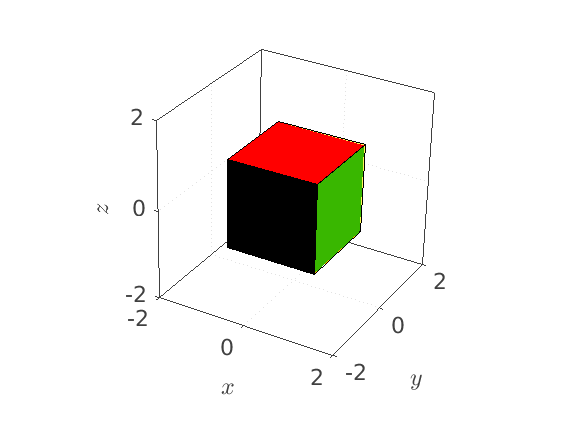

N = R*M;
Cubeplot(N');


R = [1 0 0; 0 0 1; 0 -1 0];
[u, phi] = matrix2euleruphi(R)

u =     -1
     0
     0


phi = 90

R = euleruphi2matrix(u, phi)

Your angle was changed from degrees to radians in order to operate


R =     1.0000         0         0
         0    0.0000    1.0000
         0   -1.0000    0.0000


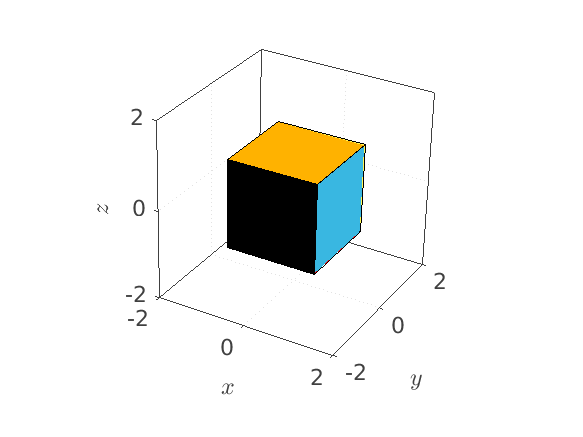

N = R*M;
Cubeplot(N');


u = [0; 1; 0]

u =      0
     1
     0


phi = 90;
q = euleruphi2quat(u, phi)

Your angle was changed from degrees to radians in order to operate


q =     0.7071
         0
    0.7071
         0


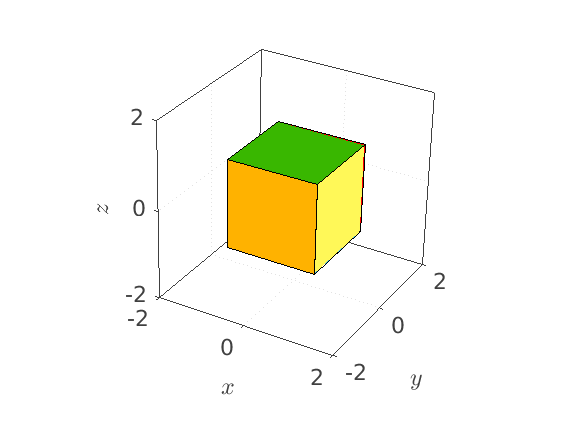

N(:, 1) = rotquat(M(:, 1), q);
N(:, 2) = rotquat(M(:, 2), q);
N(:, 3) = rotquat(M(:, 3), q);
N(:, 4) = rotquat(M(:, 4), q);
N(:, 5) = rotquat(M(:, 5), q);
N(:, 6) = rotquat(M(:, 6), q);
N(:, 7) = rotquat(M(:, 7), q);
N(:, 8) = rotquat(M(:, 8), q);
Cubeplot(N');


q = [0 1 0 0]';
[u, phi] = quat2euleruphi(q)

u =      1
     0
     0


phi = 180

R = euleruphi2matrix(u, phi)

Your angle was changed from degrees to radians in order to operate


R =     1.0000         0         0
         0   -1.0000   -0.0000
         0    0.0000   -1.0000


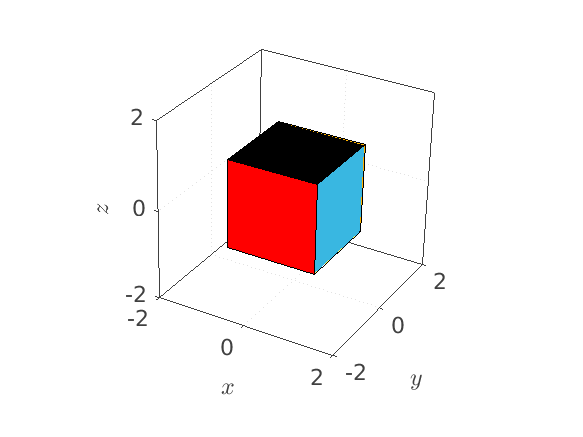

N = R*M;
Cubeplot(N');


u = [1, 0, 0];
phi = 90;
r = euleruphi2rotvec(u, phi)

Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate


r =     1.5708
         0
         0


[u, phi] = rotvec2euleruphi(r)

u =      1
     0
     0


phi = 90

R = euleruphi2matrix(u, phi)

Your angle was changed from degrees to radians in order to operate


R =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


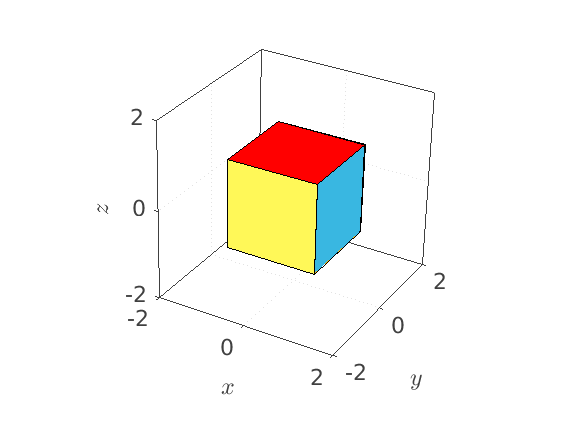

N = R*M;
Cubeplot(N');

## Exercise 2

Create a function that:

- Given {a rotation matrix or Euler rotation angles or principal Euler axis/angle or quaternion or rotation vector}, returns {a rotation matrix and Euler rotation angles and principal Euler axis/angle and quaternion and rotation vector}

Hint: use a letter 'r,e,p,q,v' to inform the function which are the input arguments. 

disp("EX2")

EX2


R = [0 0 -1; 0 1 0; 1 0 0];
[R, eulerangles, euleruphi, quaternion, rotvec] = rotation_change(R, 'r')

pitch is equal to pi/2, cannot calculate roll and yaw
Your angle was changed from degrees to radians in order to operate
Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate


R =      0     0    -1
     0     1     0
     1     0     0


eulerangles = 3×1 string array
    "NaN"
    "90"
    "NaN"


euleruphi =      0
    -1
     0
    90


quaternion =     0.7071
         0
   -0.7071
         0


rotvec =          0
   -1.5708
         0



roll = 0;
pitch = 90;
yaw = 90;
[R, eulerangles, euleruphi, quaternion, rotvec] = rotation_change([roll, pitch, yaw]', 'e')

Your pitch angle was changed from degrees to radians in order to operate
Your yaw angle was changed from degrees to radians in order to operate
Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate
Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate


R =     0.0000   -1.0000    0.0000
    0.0000    0.0000    1.0000
   -1.0000         0    0.0000


eulerangles =      0
    90
    90


euleruphi =    -0.4330
    0.4330
    0.4330
  120.0000


quaternion =     0.5000
   -0.5000
    0.5000
    0.5000


rotvec =    -1.2092
    1.2092
    1.2092



u = [0 0 -1]';
phi = 90;
[R, eulerangles, euleruphi, quaternion, rotvec] = rotation_change([u; phi], 'p')

Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate
Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate
Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate


R =     0.0000    1.0000         0
   -1.0000    0.0000         0
         0         0    1.0000


eulerangles =      0
     0
   -90


euleruphi =      0
     0
    -1
    90


quaternion =     0.7071
         0
         0
   -0.7071


rotvec =          0
         0
   -1.5708



q = [0 0 1 0]';
[R, eulerangles, euleruphi, quaternion, rotvec] = rotation_change(q, 'q')

Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate
Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate


R =    -1.0000         0    0.0000
         0    1.0000         0
   -0.0000         0   -1.0000


eulerangles =   180.0000
    0.0000
  180.0000


euleruphi =      0
     1
     0
   180


quaternion =      0
     0
     1
     0


rotvec =          0
    3.1416
         0



u = [-1 0 0]';
phi = 180;
r = euleruphi2rotvec(u, phi);

Your angle was changed from degrees to radians in order to operate


[R, eulerangles, euleruphi, quaternion, rotvec] = rotation_change(r, 'v')

Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate
Your angle was changed from degrees to radians in order to operate
Your vector was reshaped to a (3, 1) vector in order to operate


R =     1.0000         0         0
         0   -1.0000    0.0000
         0   -0.0000   -1.0000


eulerangles =   -180
     0
     0


euleruphi =     -1
     0
     0
   180


quaternion =     0.0000
   -1.0000
         0
         0


rotvec =    -3.1416
         0
         0
